# Exercise 3: Plots

The plotting framework is an invaluable tool built into MATLAB. You will notice that it is often used to represent all kinds of data in scientific research. We will cover 2D & 3D-figures, images and methods of representing statistical data.

Know that the methods suggested in the lectures provide the most essential tools, but that many more functions can be found. Consult [the MATLAB Plot Gallery](https://nl.mathworks.com/products/matlab/plot-gallery.html) to find a variety of functions representing ways to visualise data.

Please complete following modules:

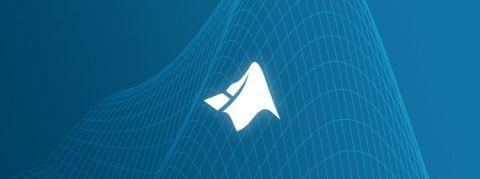

## [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted)

- Plots

- Data Import

Then, continue with following exercises:

## A. 2D figures

close all; clear all;

In the subsequent exercises, we will plot functions and figures by representing the individual data points $(x,y)$. This means that the 'smooth' function you acquire is actually a clever trick from MATLAB wherein the software connects all these individual points. However, the smoothness of your function still depends on the amount of chosen data points. Indeed, if you try representing a sinusoidal function by plotting only 3 points, this figure will in no way look like the one you intended. It is therefore that an appropriate guess of the amount of points to be represented comes in handy.

Creating such an initial variable ($x$ for our unknown) can be done in multiple ways as seen during the lectures. If you know in advance the interval between the data points, you can use:

x = 0:0.01:1;

If this is unknown and you only wish to specify the amount of points, the function `linspace()` comes in handy:

x = linspace(0,1,100);

If at any point in your analysis you observe a certain roughness in the plot, increase the amount of drawn grid points. **Be carefull not to exagerate.** Using a million points to get a grasp of the behaviour of a simple sinusoidal function is futile and will only slow down your computer.

### Exercise 1:

**A) **Plot the following functions:

- $y = \frac{1}{x}$ with a black dashed line.

- $y = \sin(x)\cos(x)$ with a green dotted line.

- $y = 2x^2 - 3x + 1$ with red triangles.

Choose the appropriate ranges for $x$ yourself in order to clearly visualise the function.

As a good practice, **always** provide your figure with a title and name the axes. A grid can also help readability.

When plotting multiple datasets on one single figure, foresee a clear legend.

**B) **Given the following function:


$$g(\phi) = \cos(\phi) + \sqrt{b^2-(\sin(\phi)-c)^2}$$


Knowing that $a = 1$, $b = 1.5$, $c = 0.3$, plot this function for $\phi \in [0\degree ,360\degree ]$.

**C) **Plot following parametric functions:

- A circle with radius 5

- A so-called *leminscate: *$\left\{ \matrix{ x & = \cos(\phi) \sqrt{2 \cos(2 \phi)} \cr y & = \sin(\phi) \sqrt{2 \cos(2 \phi)}}$ for $-\pi/4 \leq \phi \leq \pi/4$

- A *logarithmic spiral:* $\left\{ \matrix{ x &= e^{k\phi} \cos(\phi) \cr y &= e^{k \phi} \sin(\phi) }$ for $k = 0.1$ and $0 \leq \phi \leq 6 \pi$

If you notice that the figures look deformed, try the `axis equal `command to give both axes the same scale.

**D) **Compare the properties of the sine function and the cosine function on one figure.

- Use the interval $x \in [-2 \pi, 2 \pi]$

- Plot the sine function in green. Make the linewidth twice the default thickness.

- Plot the cosine function in blue. Choose an interrupted line.

- Implement a legend.

- Foresee a small grid.

After completion of your graph, you are unhappy with the layout. Use the properties of Graphics Objects to:

- Return the handle of the current figure.

- Return the objects corresponding to each line.

- Change the markers of the sine function to squares.

- Change the markers of the cosine function to triangles.

### Exercise 2:

#### Coil Spring

In 2D we can draw a coil spring (F: Ressort hélicoïdal, N: springveer) by visualising the track of a point moving along an ellipse of which the center is moving along the small axis.

The parametric equation of an ellipse is given by: $\left\{ \matrix{ x &= a \cos(t) \cr y &= b \sin(t)}$ where $a$ and $b$ are parameters denoting respectively the semi-minor and semi-major axis (assuming $a \leq b$).

Draw the figure of a simple ellipse using $a= 3$ and $b=5$

Suppose now that a 'drift' is incorporated into the movement of this point. This presents a new parametric equation:


$$\left\{ \matrix{ x &= a \cos(t) + \frac{c}{2\pi} t \cr y &= b \sin(t)}$$


The parameter $c$ represents the speed of the drift. Suppose $c= 3$ units per revolution.

Explore the possibilities when it comes to annotating your figure.

- Give the figure a tight grid.

- Optimize the axes in order to tightly fit the figure. Make them equal.

- Give the figure a title with a distinct backgroundcolor. Change the font and increase the size.

- Insert labels. Make the typing **bold**.

- Insert a legend. Choose an appropriate location outside of the figure. Give your legend a title.

### Exercise 3:

#### Spirograph

We will draw the motion of a point moving along a circle of which the center itself is also moving along a circle. Predefine the following parameters:

- The points in the input vector to be drawn.

- The number of revolutions of the center of the peripheral circle around the central circle.

- The radius of the central circle.

- The number of revolutions around the peripheral circle.

- The radius of the peripheral circle.

- Add a boolean allowing a reversal of the sense of the rotation.

## B. 3D figures

close all; clear all;

For the next exercises we must get accustomed to a slight change in reasoning. For 3D figures we must now represent a number of points having 3 coordinates $(x,y,z)$ in stead of 2. This means that there now exist 2 independent variables $(x,y)$ and one dependent variable $(z)$.

In 2D we would generate a vector of independent variables, often stored in $x$.

In 3D we must now generate a grid of independent variables, stored in both $x$ and $y$. This is where the `meshgrid()` command comes in. The meshgrid command will create all possible combinations of the elements of $x$ with the elements of $y$. We will demonstrate this with the following example:

Thanks to the meshgrid command, we have created a grid spanning the $xy$-plane of the domain we wish to picture. All possible values of $x$ are stored in `X` and all possible values of $y$ are stored in` Y`

If you now want to start making 3D figures, we must compute the corresponding $z$ value for all these gridpoints.

### Exercise 1:

Create a 3D plot of the function $f(x,y) = \sin(x) \cos(y)$ . Plot the function for values of $x,y \in \left[-2,2\right]$. Choose the intervals of the axes appropriately.

### Exercise 2:

**A) **Of course we can also draw curves in 3D. This means we are not representing a 'mesh' but a 3D-line. Use the `plot3() `function to draw:

- A spherical helix: $\left\{ \matrix{x &= \sin\left(\frac{t}{2c}\right)\cos(t) \cr y & = \sin\left(\frac{t}{2c}\right)\sin(t) \cr z &= \cos\left(\frac{t}{2c}\right)}$ where $c=5$ and $0 \leq t \leq 10 \pi$.

- A sine wave on a sphere: $\left\{ \matrix{x &= \cos(t) \sqrt{b^2-c^2 \cos^2(at)} \cr y &= \sin(t) \sqrt{b^2-c^2 \cos^2(at)} \cr z &= c \cos(at)}$ where $a=10$, $b=1$, $c=0.3$ and $0 \leq t \leq 2\pi$.

**B) **Plot following surfaces using the `surf()` function:

- Sine surface: $\left\{ \matrix{ x & = \sin(u) \cr y &= \sin(v) \cr z &= \sin(u+v)}$ where $u,v \in [0,2\pi]$

- Spring: $\left\{ \matrix{ x & = (1-r_1 \cos(v))\cos(u) \cr y & = (1 - r_1 \cos(v)) \sin(u) \cr z &= r_2 (\sin(v) + \frac{t u}{\pi}) }$ where $r_1 = r_2 = 0.5$ , $t = 1.5$, $0 \leq u \leq 10 \pi$ and $0 \leq v \leq 10 \pi$

- Elliptic torus: $\left\{ \matrix{ x &= \left(c + \cos(v)\right) \cos(u) \cr y &= \left(c+ \cos(v)\right)\sin(u) \cr z &= \sin(v) \cos(v) }$ where $c = 0.5$, $-\pi \leq u \leq \pi$ and $0 \leq v \leq \pi$

Hint: Look up the difference between `surf() `and `mesh()` in the documentation.

Consult the documentation:

- Use the `shading interp` command after `surf()` to change the type of shading of the first figure. Add a `colorbar` to the figure.

- Change the illumination of the second figure.

- Open the last figure, the elliptic torus in a dedicated figure window. Use the interface to insert labels, titles and any more options to your liking. Once completed, use the appropriate procedure to save the figure as a .fig and as a .png file. Try and reproduce the code required to create this last figure.

### Exercise 3:

Draw the following function using surf, mesh and contour:


$$z=\frac{2\left(x^{2}-1\right)\left(y^{2}-1\right) \sin (20 x)}{5}$$


Draw this function over the interval $x \in [-1,1]$ and $y \in [-1,1]$.

Use the subplot command to represent the 3 different methods in one figure environment. Make the axes equal.

## C. Images:

close all; clear all;

Open the earth.mat file into your workspace.

Generate the image of the earth

## D. Statistics:

close all; clear all;

### Exercise 1:

- Generate two vectors $x$ and $y$ with 100 normally distributed values.

- Create a scatterplot of $x$ and $y$.

- Find the mean ( $\mu$ ) and standard deviation ($\sigma$) of $x$ and $y$ respectively.

- Draw the point $(\mu_x,\mu_y)$ as a 'pentagram' in red.

- Connect the points $(\mu_x - 2 \sigma_x, \mu_y)$ and $(\mu_x + 2 \sigma_x, \mu_y)$ with a red dotted line. Put a hexagram as a marker.

- Connect the points $(\mu_x, \mu_y - 2 \sigma_y)$ and $(\mu_x, \mu_y + 2 \sigma_y)$ with a red dotted line. Put a hexagram as a marker.

- Give all points falling outside of the range determined in the two bullets above a yellow colour.

### Exercise 2:

MATLAB also possesses some tools to plot statistical data. Revisit [the MATLAB Plot Gallery](https://nl.mathworks.com/products/matlab/plot-gallery.html) to solve the following exercise.

Each year the HR service of the Belgian Defence presents its annual report: [NL](https://intranet.mil.intra/sites/Pers/Jaarverslag/2022/20230315_IU_Jaarverslag_DGHR_2022_NL.pdf) - [FR](https://intranet.mil.intra/sites/Pers/Jaarverslag/2022/20230315_IU_RapportAnnuel_DGHR_2022_FR.pdf)

As you can see, this report contains impressive amounts of data.

For the first exercise focus only on point 1.a.(3) on page 12. Create a pie chart giving the distribution of all personnel working within the Belgian Defence by their component. Highlight the piece corresponding to your component. Use the documentation to annotate the chart.